# Reaction-Diffusion Equation

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Reaction-diffusion systems describe how the concentration of one or more substances distributed in space changes under the influence of two processes: local chemical reactions, which create or destroy substances, and diffusion, which causes substances to spread out in space. These systems are modeled by partial differential equations (PDEs). They are used to simulate patterns in chemical and biological systems, such as animal skin patterns, chemical oscillations, and the formation of structures in developing organisms.

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will help you become familiar with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free two-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if they run out of order.

## Reaction diffusion model for morphogenesis

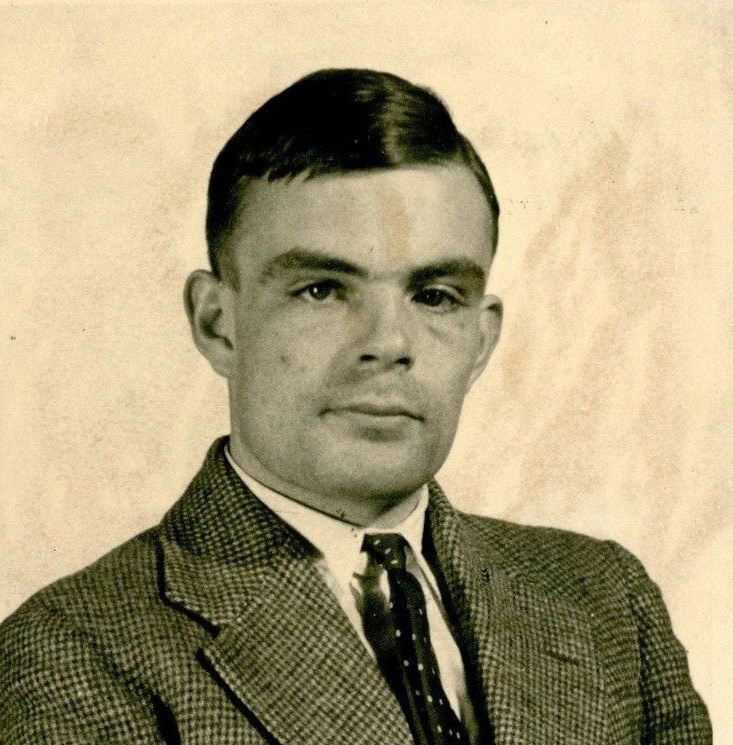

Alan Turing, [Princeton University Archives](https://i0.wp.com/universityarchives.princeton.edu/wp-content/uploads/sites/41/2014/11/Turing_Card_1.jpg?ssl=1)

Alan Turing, the famous English mathematician and one of the pioneers of computing, was interested in how a spatially homogeneous system, such as a uniform ball of cells, can generate a spatially inhomogeneous but static pattern, such as the stripes of a zebra. The [Turing Pattern](https://en.wikipedia.org/wiki/Turing_pattern) concept was introduced by him in a 1952 paper titled "[The Chemical Basis of Morphogenesis](https://en.wikipedia.org/wiki/The_Chemical_Basis_of_Morphogenesis)" which describes how [patterns in nature](https://en.wikipedia.org/wiki/Patterns_in_nature), such as stripes and spots, can arise naturally and autonomously from a homogeneous, uniform state.

In recent times, reaction–diffusion systems have attracted much interest as a prototype model for [pattern formation](https://en.wikipedia.org/wiki/Pattern_formation) [[1]](https://en.wikipedia.org/wiki/Reaction%E2%80%93diffusion_system#cite_note-:0-20). The above-mentioned patterns (fronts, spirals, targets, hexagons, stripes and dissipative solitons) can be found in various types of reaction–diffusion systems in spite of large discrepancies e.g. in the local reaction terms. It has also been argued that reaction–diffusion processes are an essential basis for processes connected to [morphogenesis](https://en.wikipedia.org/wiki/Morphogenesis) in biology [[2]](https://en.wikipedia.org/wiki/Reaction%E2%80%93diffusion_system#cite_note-21).


$$\frac{\partial A}{\partial t} = D_A \nabla^2A - AB^2 + f(1-A)$$



$$\frac{\partial B}{\partial t} = D_B \nabla^2B + AB^2+f(k+B)$$


Here,

- $A$, $B$ are concentrations

- $D_A$, $D_B$ represent respective diffusion coefficients

- $f$ is the scaled feed rate

- $k$  is the scaled kill term

- Reaction term is $AB^2$ as it occurs whenever there is one $A$ and $2B$

This pair of equations models the interactions between two elements that might be pigments or other chemicals that can create beautiful and intricate patterns through such interactions. 

## Numerical computation of solution

We can model this reaction ourselves by discretizing the system of equations with a time step $\Delta t$ as given below:


$$A(x,y,t+\Delta t) = A(x,y,t) + (D_A\nabla^2A(x,y,t) - A(x,y,t)B(x,y,t)^2 + f(1-A(x,y,t)))\Delta t$$



$$B(x,y,t+\Delta t) = B(x,y,t) + (D_B \nabla^2B(x,y,t) + A(x,y,t)B(x,y,t)^2 + f(k+B(x,y,t)))\Delta t$$


### Approximate the Laplacian

To approximate the 2D Laplacian, $\nabla^2 = \frac{\partial^2}{\partial x^2} + \frac{\partial^2}{\partial y^2}$, we'll use the central difference formula for the second derivatives. Let's consider a uniform square grid with spacing $h$ in both $x$ and $y$ directions. For a point $(𝑥,𝑦)$, let $M_{i,j}$ be the function value at the grid point corresponding to $(x_i,y_j)$.

The second derivative with respect to $x$ at point $(𝑥,𝑦)$ can be approximated as:


$$\frac{\partial^2 M}{\partial x^2} \approx \frac{M(x+h,y) - 2M(x,y) + M(x-h,y)}{h^2} = \frac{M_{i+1,j} - 2M_{i,j} + M_{i-1,j}}{h^2}$$


Similarly, the second derivative with respect to $y$ is:

$\frac{\partial^2 M}{\partial y^2} \approx \frac{M(x,y+h) - 2M(x,y) + M(x,y-h)}{h^2} = \frac{M_{i,j+1} - 2M_{i,j} + M_{i,j-1}}{h^2}$.

Adding these two approximations gives the approximation for the Laplacian:


$$\nabla^2 M \approx \frac{M_{i+1,j} + M_{i-1,j} + M_{i,j+1} + M_{i,j-1} - 4M_{i,j}}{h^2}$$


This formula represents the five-point stencil, with the point of interest in the center surrounded by its four immediate neighbors in the grid.

MyLaplacian = @(M)NinePointLaplacian(M);

### Reaction-Diffusion Parameters

Set values for the diffusion coefficients, feed rate, and kill term.

da = 1;                    % Diffusion coefficient for A
db = 0.5;                  % Diffusion coefficient for B
f = 0.055;  % Scaled feedrate
k = 0.063;  % Scaled killterm

Set a value that determines the number of pixels on the side length of your square region. Increasing this value can significantly slow down the simulation. Decreasing it will make the simulation faster at the cost of pixelation. 

width = 120; % This is the number of pixels

Set values for the time step and the stop time, and compute the number of timesteps used in this simulation.

dt = .25;             % Timestep
stoptime = 5000;      % This value must be an integer multiple of dt
Nt = stoptime/dt+1;   % How many timesteps to take

### Solution of the equation

First, set up the initial conditions for the system:

[t0, A, B] = initial_conditions(width,InitVals=1);

Draw the initial result and iterate through numerically approximating system updates with the chosen Laplacian approximation.

hi = image(B);
hi.CDataMapping = "scaled";
for idx = 1:Nt
    anew = A + (da*MyLaplacian(A) - A.*B.^2 + f*(1-A))*dt;
    bnew = B + (db*MyLaplacian(B) + A.*B.^2 - (k+f)*B)*dt;
    A = anew;
    B = bnew;
    if idx <= 5
        hi.CData = B;
        drawnow
    elseif idx <= 20 && mod(idx,2) == 0
        hi.CData = B;
        drawnow

After the first 20 updates, use the slider to select how frequently to draw new frames for the animation of the results. 

    % Skipping frames, draw the new scaled-color image
    elseif mod(idx,99)==1
    hi.CData = B;
    drawnow 
    end
end

  **Try**. Experiment with different values of $f$ and $k$. Do you see any differences in the behavior?

### A Better Approximation of the Laplacian

To derive the nine-point stencil, we start with the standard five-point stencil approximation and then incorporate corrections that account for the diagonal neighbors, thus improving the accuracy to fourth order.

For a uniform grid with spacing $h$ in both $x$ and $y$ directions, the nine-point stencil can be derived by combining the Taylor series expansions of $M$at the point $(x_i,y_j)$, including diagonal points. The key idea is to add a correction term to the standard five-point stencil that involves the diagonal neighbors $(x\pm h,y\pm h)$.

The [Patra-Karttunen stencil](https://en.wikipedia.org/wiki/Nine-point_stencil) is given by:

$\nabla^2 M \approx \frac{1}{6h^2} \left( 4M_{i+1,j} + 4M_{i-1,j} + 4M_{i,j+1} + 4M_{i,j-1} + M_{i+1,j+1} + M_{i-1,j-1} + M_{i+1,j-1} + M_{i-1,j+1} - 20M_{i,j} \right)$.

This approximation involves the direct neighbors (as in the five-point stencil) and the four diagonal neighbors, with coefficients designed to achieve fourth-order accuracy. 

  **Try**. Go back to the choice of a Laplacian. Using the nine-point Laplacian approximation, test the response of this system with different parameters.

- Can you generate patterns of spots? Stripes? Mazes? Kaleidoscopic change?

- Extend the `stoptime` to 5000 or longer. You can reduce the frequency at which the state is drawn by increasing the value of the slider.

- Change the initial data. Does this impact the evolution of the system?

 **Reflect**.

- Do you reach different results when using a 5-point stencil versus a 9-point stencil in this system? Why or why not?

- Do the patterns that you create remind you of any images from the natural world?

- Can you predict the images that will result from your initial conditions? Why or why not?

## Using the PDE Toolbox: Additional Dimensions

The Partial Differential Equation Toolbox$^{\trademark}$ solves systems of equations of the form


$$\mathbf{m}\frac{\partial^2\mathbf{u}}{\partial t^2} + \mathbf{d}\frac{\partial \mathbf{u}}{\partial t} - \nabla\cdot (\mathbf{c} \otimes \nabla \mathbf{u}) + \mathbf{a}\mathbf{u} = \mathbf{f}$$


where $\textbf{m}$, $\textbf{d}$, $\textbf{a}$, and $\textbf{f}$ are $N$-by-$N$ matrices for $N$ equations, and $\textbf{c}$ is a square tensor of twice the spatial dimensions. Recall that our formulation was:


$$\frac{\partial A}{\partial t} = D_A \nabla^2A - AB^2 + f(1-A)$$



$$\frac{\partial B}{\partial t} = D_B \nabla^2B + AB^2+f(k+B)$$


In this case, we have a system of equations where 

$\textbf{u} = \left[\matrix{A \cr B}\right]$,     $\textbf{m} = \left[\matrix{0\cr0}\right]$,     $\textbf{d} = \left[\matrix{1\cr1}\right]$,     $\textbf{c} = \left[\matrix{D_a\cr D_b}\right]$,     $\textbf{a} = \left[\matrix{f\cr -f}\right]$,     and     $\textbf{f} = \left[\matrix{-AB^2+f\cr AB^2+fk}\right]$.

% Set up the geometry
model = createpde(2);

% Start with a solid cube
gmCube = multicuboid(1,1,1);
% Cut a void out of the center
gmHole = multicuboid(0.6,0.2,0.9);
gmHole = translate(gmHole,[0,0,0.05]);
gm = addVoid(gmCube,gmHole);
pdegplot(gm,"FaceAlpha",0.4)
model.Geometry = gm;
msh = generateMesh(model,"GeometricOrder","linear");
pdeviz(msh,"Transparency",0.3);

After setting up the geometry, you can define the parameters of the PDEs:

% Parameters of the PDEs
da = 1;
db = 0.5;
f = 0.026;
k = 0.053;

% Define the vectors needed to represent the system
dVec = [1;1];
cVec = [da;db];
aVec = [f;-f];
fVec = @(region,state) [f-state.u(1,:).*state.u(2,:).^2;...
    state.u(1,:).*state.u(2,:).^2 + f*k];

% Set the coefficients in the PDE object model
specifyCoefficients(model,"m",0,"d",dVec,"c",cVec,"a",aVec,"f",fVec);

And the values of the initial conditions:

% Specify initial conditions
icFcn = @(region) [sin(2*pi*region.x).*cos(2*pi*region.z);...
cos(6*pi*region.y).*sin(6*pi*region.x)];
setInitialConditions(model,icFcn);

% Set up the time vector
tlist = linspace(0,0.05,50);

% Compute the results
results = solvepde(model,tlist);
disp("Results computed.")

Visualize the results of the computation.

% Extract the results for B, starting with the initial values
nodalData = results.NodalSolution(:,2,1);

% Create PDE result visualization
resultViz = pdeviz(msh,nodalData, ...
    "AxesVisible",false, ...
    "MeshVisible",true, ...
    "ColorLimits",[0 1], ...
    "Transparency",0.4,...
    "Title","Initial Conditions");

% Animate the results for B
for ii2 = 1:(length(tlist)+10)
    if ii2<=10
        % Show the initial conditions for 10 frames in the animation
        resultViz.NodalData = nodalData;
    else 
        % Show the evolution of B over time
        resultViz.NodalData = results.NodalSolution(:,2,ii2-10);
        % rescale the colorbar for visibility into the variation
        resultViz.ColorLimits = [0 min([1,max(resultViz.NodalData)+0.01])];
        resultViz.Title = "Evolving";
    end
    pause(0.1)
end

  **Try**.

- Change the geometry. Start by changing the dimensions of the void, but feel free to explore other [geometries](https://www.mathworks.com/help/pde/geometry-and-mesh.html) as well.

- Change the parameters $f$ and $k$. What impact does that have on your result?

- Change the initial conditions. What impact does that have on your result? 

## Further Explorations

- This documentation example uses [cross-coupling](https://www.mathworks.com/help/pde/ug/nonlinear-system-with-cross-coupling-between-components.html) to illustrate the delicate balance of calculating solutions to PDEs.

- This documentation example computes [eigenfunctions for a surface](https://www.mathworks.com/help/pde/ug/eigenvalues-and-eigenfunctions-for-the-l-shaped-membrane.html).

### Acknowledgments

This script builds on work originated by Deb Singdeo and Spandhana Gonuguntla, both from MathWorks.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

function out = FivePointLaplacian(in)


$$\frac{\partial^2 B_{i,j}}{\partial x^2}+ \frac{\partial^2 B_{i,j}}{\partial y^2} \approx -B_{i,j} + \frac{(B_{i+1,j}+B_{i-1,j} + B_{i,j+1}+B_{i,j-1})}{4}$$


Periodic boundary conditions

out = -4*in ...
    + (circshift(in,[ 1, 0]) + circshift(in,[-1, 0])  ...
    +  circshift(in,[ 0, 1]) + circshift(in,[ 0,-1]));
end

⇦ Return to text

function out = NinePointLaplacian(in)


$$\frac{\partial^2 B_{i,j}}{\partial x^2}+ \frac{\partial^2 B_{i,j}}{\partial y^2} \approx -B_{i,j} + \frac{1}{5}(B_{i+1,j}+B_{i-1,j} + B_{i,j+1}+B_{i,j-1}) + \frac{1}{20}\left(B_{i+1,j+1}+B_{i-1,j+1}+B_{i-1,j-1}+B_{i+1,j-1}\right)$$


Periodic boundary conditions

out = -in ...
    + 0.20*(circshift(in,[ 1, 0]) + circshift(in,[-1, 0])  ...
    +       circshift(in,[ 0, 1]) + circshift(in,[ 0,-1])) ...
    + 0.05*(circshift(in,[ 1, 1]) + circshift(in,[-1, 1])  ...
    +       circshift(in,[-1,-1]) + circshift(in,[ 1,-1]));
end

⇦ Return to text

function [t, A, B] = initial_conditions(n,opts)
arguments
    n 
    opts.InitVals {mustBeMember(opts.InitVals,1:3)} = 1
end
t = 0;
% Initialize A to one
A = ones(n);
B = zeros(n);

if opts.InitVals == 1
    % Initialize B with several clumps of ones
    idx1 = n/2-29;
    idx2 = n/2-20;
    idx3 = n/2-10;
    idx4 = n/2+10;
    idx5 = n/2+20;
    B(idx1:idx2,idx1:idx3) = 1;
    B((idx2+1):n/2,(idx3+1):n/2)=1;
    B(idx4:idx5,idx4:idx5) = 1;
elseif opts.InitVals == 2
    % Initialize B with a border of ones
    B(:,1:3) = 1;
    B(:,end-2:end) = 1;
    B(1:3,:) = 1;
    B(end-2:end,:) = 1;
elseif opts.InitVals == 3
    % Initialize B with a greyscale image
    load("Mouse.mat","mouse")
    if n<192
        B = 1-mouse((n-192)/2+1:(n-192)/2+n,((500-n)+1):500);
    elseif n<500
        B(((n-192)/2+1):(n+192)/2,:) = 1-mouse(:,((500-n)+1):500);
    else
        B(((n-192)/2+1):(n+192)/2,1:500) = 1-mouse;
    end
end
end

**Hint:** Notes on choices of initial conditions.

% f = 0.055 and k = 0.062 generates a brain-coral type pattern
% f = 0.054 and k = 0.061 generates a maze-type pattern
% f = 0.026 and k = 0.062 generates spots
% f = 0.037 and k = 0.062 generates spots and lines
% f = 0.013 and k = 0.053 is pretty (moving dots) or k=0.051 (moving squiggles)
% f = 0.013 and k = 0.049 moving spirals, but k=0.047 dies out
% f = 0.017 and k = 0.049 concentric circles with original ICs
% f = 0.017 and k = 0.042 elaborate flashing patterns
% f = 0.017 and k = 0.044 stripey flashing patterns
% f = 0.018 and k = 0.051 particularly kaleidoscopic with border ICs